clc; clear; close all;
disp("MATLAB Exercise: Denavit_Hartenberg to T(Standar DH)")

MATLAB Exercise: Denavit_Hartenberg to T(Standar DH)


n=9;
DH = [0,0,0,0;
    0,0,50,0;
    90,0,0,90;
    0,260,0,0;
    90,0,200,0;
    0,0,170,90;
    90,30,0,90;
    90,0,0,0;
    0,0,0,0
    ];
% for j=1:n
%     DH(j, :) = input(sprintf('input [alpha_{%d}, a_{%d}, d_%d, theta_%d]: ', j-1, j-1, j, j));
% end
disp('DH = ');

DH = 


disp(DH);

     0     0     0     0
     0     0    50     0
    90     0     0    90
     0   260     0     0
    90     0   200     0
     0     0   170    90
    90    30     0    90
    90     0     0     0
     0     0     0     0



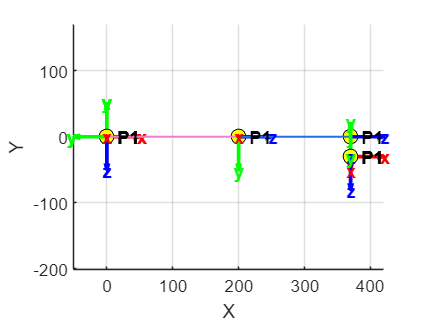

DH_T_{0}_{1}


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_0

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{1}_{2}


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_1

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{2}_{3}


$$\left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_2

$$\left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{3}_{4}


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 260\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_3

$$\left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 310\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{4}_{5}


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & -200\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_4

$$\left(\begin{array}{cccc} 0 & 0 & 1 & 200\\ 0 & -1 & 0 & 0\\ 1 & 0 & 0 & 310\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{5}_{6}


$$\left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 170\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_5

$$\left(\begin{array}{cccc} 0 & 0 & 1 & 370\\ -1 & 0 & 0 & 0\\ 0 & -1 & 0 & 310\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{6}_{7}


$$\left(\begin{array}{cccc} 0 & -1 & 0 & 30\\ 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_6

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 370\\ 0 & 1 & 0 & -30\\ 0 & 0 & 1 & 310\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{7}_{8}


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_7

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 370\\ 0 & 0 & -1 & -30\\ 0 & 1 & 0 & 310\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{8}_{9}


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_8

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 370\\ 0 & 0 & -1 & -30\\ 0 & 1 & 0 & 310\\ 0 & 0 & 0 & 1 \end{array}\right)$$

syms theta alpha d a
% Rotation matrices
Rz = [cos(theta), -sin(theta), 0;
    sin(theta),  cos(theta), 0;
    0,          0,          1];
Rx = [1, 0,         0;
    0, cos(alpha), -sin(alpha);
    0, sin(alpha), cos(alpha)];
Dz=[0;0;d];
Dx=[a;0;0];
O=[0;0;0];
O3=eye(3);
T_Rz=[Rz,O;0,0,0,1];
T_Rx=[Rx,O;0,0,0,1];
T_Dz=[O3,Dz;0,0,0,1];
T_Dx=[O3,Dx;0,0,0,1];
DH_T_nd1_n=T_Rx*T_Dx*T_Rz*T_Dz;%{i}相对于{i-1}映射的齐次变换矩阵

DH_I=eye(4);
R_all_abs=NaN(3,3,n+1);
p_ALL_abs=NaN(3,1,n+1);
p_ALL_rela=NaN(3,1,n+1);
R_all_abs(:,:,1)=O3;
p_ALL_abs(:,:,1)=O';
p_ALL_rela(:,:,1)=O';
figure; hold on; grid on; axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
for j=1:n
    DH_cal=subs(DH_T_nd1_n,[theta,alpha,a,d],[deg2rad(DH(j,4)),deg2rad(DH(j,1)),DH(j,2),DH(j,3)]);
    fprintf('DH_T_{%d}_{%d}\n',j-1,j);
    disp(DH_cal);
    fprintf('DH_T_0_%d',j-1);
    DH_I=DH_I*DH_cal;
    disp(DH_I);
    %R=DH_I(1:3,1:3);%提取出绝对旋转矩阵，表示姿态
    %P=DH_I(1:3, 4);%提取绝对位置矢量
    R_all_abs(:,:,j+1)=DH_I(1:3, 1:3);
    p_ALL_abs(:,:,j+1)=DH_I(1:3,4);
    p_ALL_rela(:,:,j+1)=DH_cal(1:3,4);
    % drawFrameAndPoint需要的是相对坐标
    drawFrameAndPoint(p_ALL_abs(:,:,j),R_all_abs(:,:,j),p_ALL_rela(:,:,j+1));
end